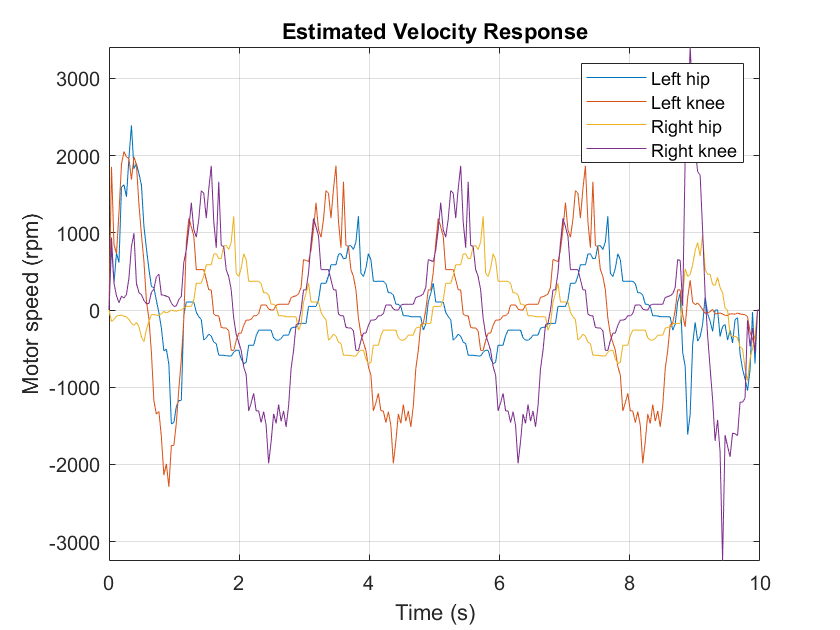

close all
load exp4Msim
load exp2Msetup
k_gear = 100;
a = 1.6875e-4;
theta_f = 0;
theta_i = 0;
theta__dot_f = 0;
theta__dot_i = 0;
theta__ddot_i = 0;

theta = JointTrajFit(sm_t1,a,t_f,theta_f,theta_i,theta__dot_f,theta__dot_i,theta__ddot_i);

sm_veltraj = convangvel(diff(100*sm_traj1)/sm_t1(2),'rad/s','rpm');
sm_veltraj = [zeros(1,size(sm_veltraj,2)); sm_veltraj];

f1 = figure;
plot(sm_t1, sm_veltraj)
legend('Left hip','Left knee','Right hip','Right knee')
title('Estimated Velocity Response')
xlabel('Time (s)'), ylabel('Motor speed (rpm)')
grid on, axis tight

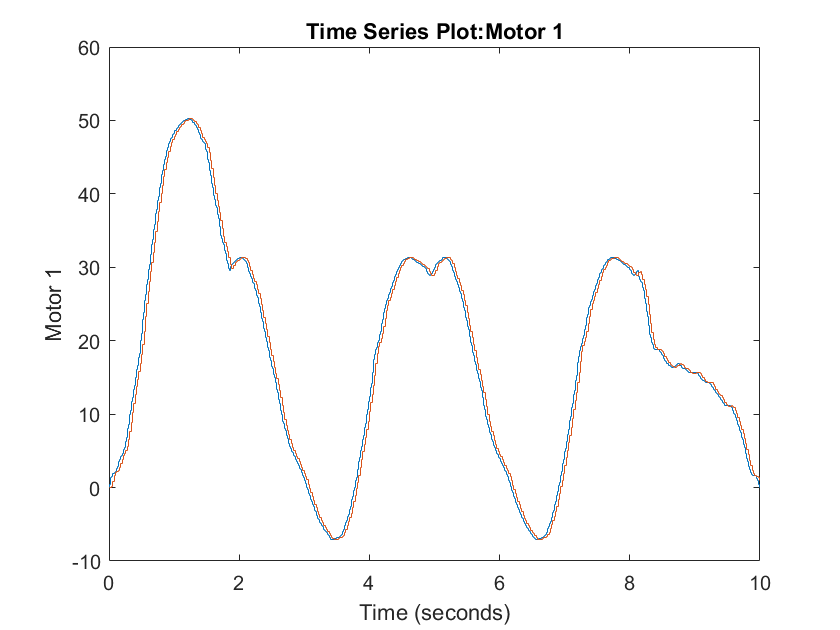

Motor1Pos = simOut1.logsout{5}.Values;
Motor2Pos = simOut1.logsout{6}.Values;
plot(Motor1Pos)

a0 = 0
